# PROBLEMAS

- Cuando se cierra el lazo T(s),  para frecuencia 0 es decir continua T(0)=0.5. Y no se como solucionarlo sin mandarle mucha ganancia que lo destabilice

- Otra cosa es que no tiene completamente automatizado el crear el controlador

Hago un modelo FOPDT con los datos extraídos de la simulación del proteus, idealmente cuando tenga la placa voy a tener que hacerlo con los datos reales. Pero por el momento para implementar el PID sirve.

clc; clear all;
s=tf('s');
z=tf('z');

Cargo los datos del proteus

data_proteus = importdata('step_response_fed_uc.DAT')

data_proteus = struct with fields:
          data: [1698713×4 double]
      textdata: {'"TIME"'  '"PB4"'  '"readV"'  '"V_PWM"'}
    colheaders: {'"TIME"'  '"PB4"'  '"readV"'  '"V_PWM"'}



time = data_proteus.data(:, 1)

time =          0
    0.0020
    0.0040
    0.0080
    0.0160
    0.0320
    0.0640
    0.0650
    0.0650
    0.0650


y = data_proteus.data(:, 3)

y =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


pb4 = data_proteus.data(:, 2)

pb4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



STEP_GAIN = 1-0.8

STEP_GAIN = 0.2000

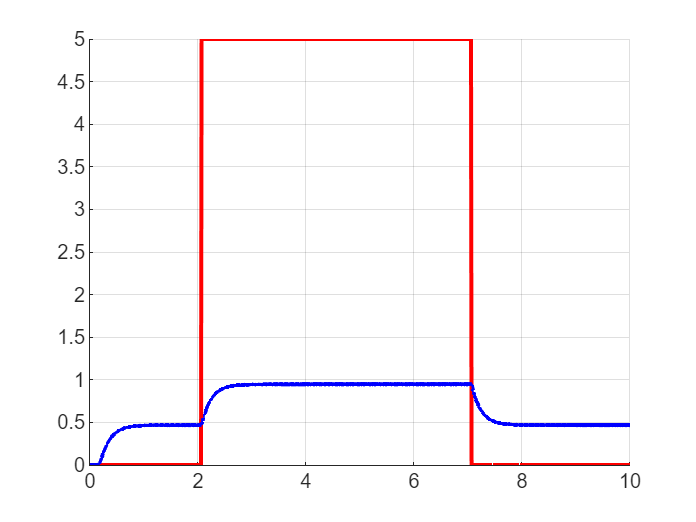

figure();
hold on; grid on;

plot(time, pb4, 'r', 'LineWidth', 2);
plot(time, y, 'b', 'LineWidth', 2);

Arreglo para quedarme con el escalón de subida y el de bajada

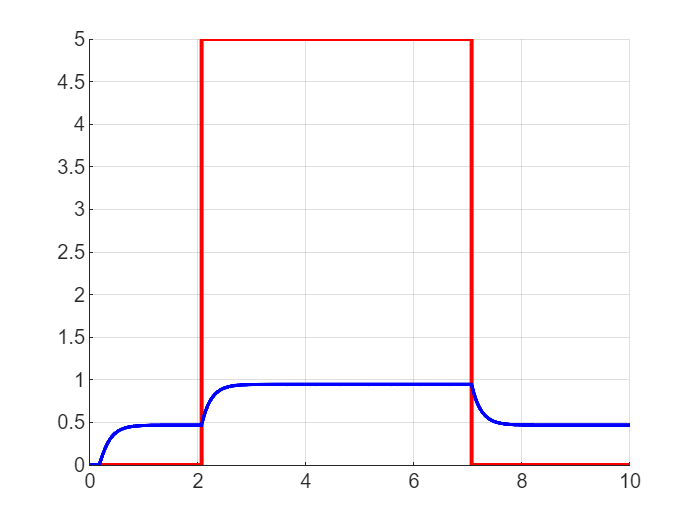

Ts=1e-3;
linear_time = 0:Ts:10;
linear_y = interp1(time, y, linear_time);
linear_pb4 = interp1(time, pb4, linear_time);

figure();
hold on; grid on;

plot(linear_time, linear_pb4, 'r', 'LineWidth', 2);
plot(linear_time, linear_y, 'b', 'LineWidth', 2);

Me quedo con el escalón de subida

step_up_start = find(linear_pb4 > 4.5, 1, 'first')-1

step_up_start = 2067

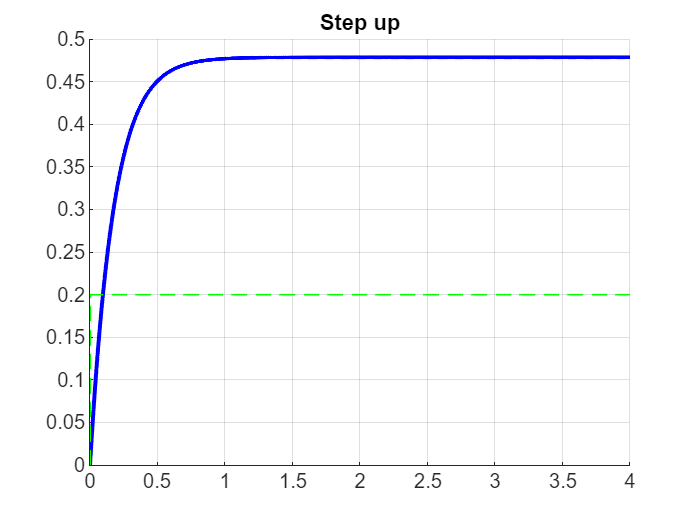

step_up_end = 4/Ts+step_up_start;

step_up_resp = linear_y(step_up_start:step_up_end)-linear_y(step_up_start);
step_up_time = linear_time(step_up_start:step_up_end)-linear_time(step_up_start);
step_up_real = linear_pb4(step_up_start:step_up_end);
step_up = STEP_GAIN*ones(1, length(step_up_real)); step_up(1)=0;

figure();
hold on; grid on;
title('Step up');

plot(step_up_time, step_up_resp, 'b', 'LineWidth', 2);
plot(step_up_time, step_up, 'g--', 'LineWidth', 1);

Ahora hago lo mismo pero para el escalón de bajada

step_down_start = find(linear_pb4 > 0, 1, "last")

step_down_start = 7067

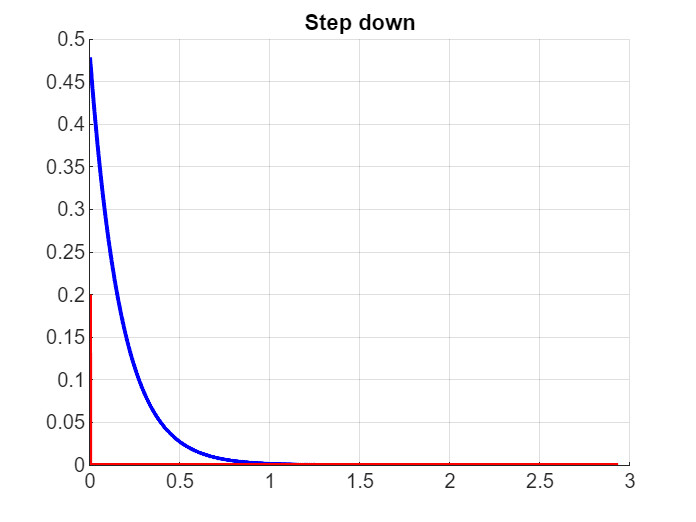


step_down_resp = linear_y(step_down_start:end)-linear_y(end);
step_down_time = linear_time(step_down_start:end)-linear_time(step_down_start);
step_down = zeros(1, length(step_down_resp)); step_down(1) = STEP_GAIN;

figure();
hold on; grid on;
title('Step down');

plot(step_down_time, step_down_resp, 'b', 'LineWidth', 2);
plot(step_down_time, step_down, 'r', 'LineWidth', 2);

Modelo FOPDT resultante:

Kp=2.3926;
Tp1 = 0.17583;
Td = 0;

Gs = Kp/(1+Tp1*s);
Gs.InputDelay = Td


Gs =
 
     2.393
  ------------
  0.1758 s + 1
 
Continuous-time transfer function.
Model Properties


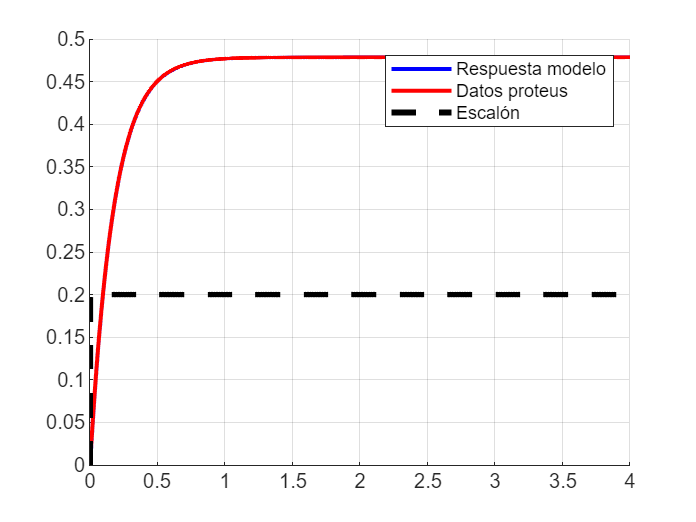

Gs_discrete = c2d(Gs, Ts);
[G_A, G_B, G_C, G_D] = tf2ss(Gs_discrete.Numerator{1}, Gs_discrete.Denominator{1});

[model_resp, ~] = lsim(Gs, step_up, step_up_time);

figure();
hold on; grid on;

plot(step_up_time, model_resp, 'b', 'LineWidth', 2);
plot(step_up_time, step_up_resp, 'r', 'LineWidth', 2);
plot(step_up_time, step_up, 'k--', 'LineWidth', 3);

legend('Respuesta modelo', 'Datos proteus', 'Escalón');

Diseño el controlador basandome en el modelo FOPDT.

Voy a cancelar el polo con un cero  de mi controlador y voy a setear un polo con ganancia para ajustar la dinámica para que sea más rápida

T0 = Tp1*1.5;
Kc = 1/Kp; % POR QUÉ CAMBIA LA GANNACIA DEL SISTEMA (AHORA LA TENGO QUE AJUSTAR CON KC)
C = Kc*(s*Tp1+1)/(s*T0+1)


C =
 
  0.07349 s + 0.418
  -----------------
    0.2637 s + 1
 
Continuous-time transfer function.
Model Properties



CL_SYSTEM = Gs*C/(1+Gs*C)


CL_SYSTEM =
 
        0.008154 s^3 + 0.1237 s^2 + 0.6154 s + 1
  -----------------------------------------------------
  0.002151 s^4 + 0.04892 s^3 + 0.4096 s^2 + 1.495 s + 2
 
Continuous-time transfer function.
Model Properties


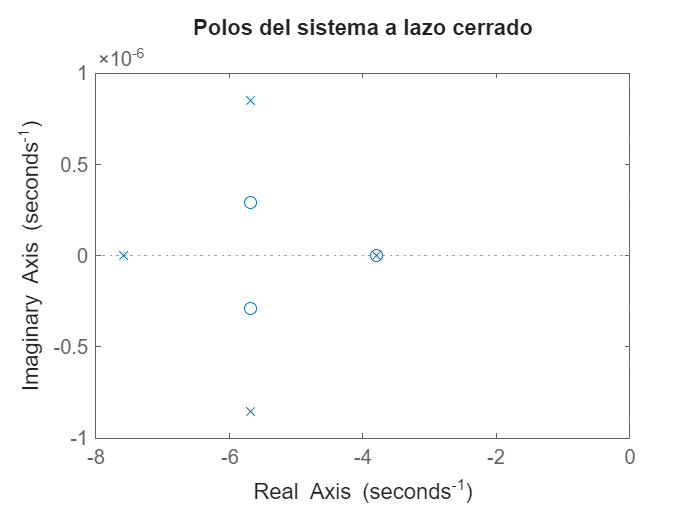

CL_SYSTEM_PADE=pade(CL_SYSTEM, 2);

figure();
pzmap(CL_SYSTEM_PADE);
title('Polos del sistema a lazo cerrado');

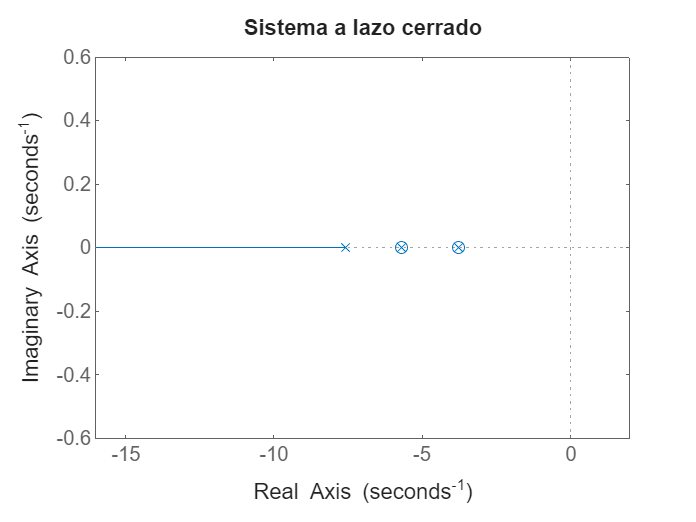


figure();
rlocus(CL_SYSTEM_PADE);
title('Sistema a lazo cerrado');

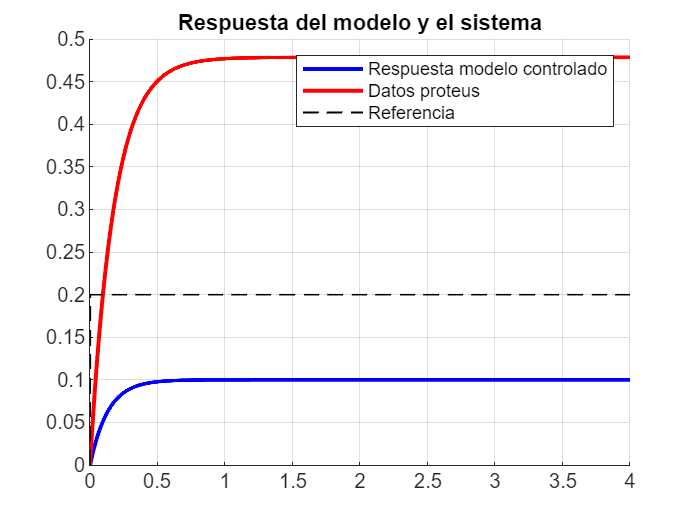


[c_step_resp, ~] = lsim(CL_SYSTEM, step_up, step_up_time);

gain_net = c_step_resp(end);
REFERENCE_GAIN=1/gain_net;

figure();
hold on; grid on;
title('Respuesta del modelo y el sistema')

plot(step_up_time, c_step_resp, 'b', 'LineWidth', 2);
plot(step_up_time, step_up_resp, 'r', 'LineWidth', 2);
plot(step_up_time, step_up, '--k', 'LineWidth', 1);

legend('Respuesta modelo controlado', 'Datos proteus', 'Referencia');

Discretizo y lo paso a esc en diferencias para calcular las ganancias

C_discrete = c2d(C, Ts)


C_discrete =
 
  0.2786 z - 0.2771
  -----------------
     z - 0.9962
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


[Cnum, Cden] = tfdata(C_discrete, 'v')

Cnum =     0.2786   -0.2771


Cden =     1.0000   -0.9962



SCALE_FACTOR = 1e3;
voltage_e_gains = (Cnum)

voltage_e_gains =     0.2786   -0.2771


voltage_u_gain = -Cden(2)

voltage_u_gain = 0.9962

Guardo en un archivo .h las ganancias del controlador

filename = "voltage_controller.h";
filepath = strcat('../../codigo_fed_uc/include/', filename);
fid = fopen(filepath, 'w');
if fid == -1
    error('Error opening the file: %s', filepath);
end

%% Header guard
guard = upper(strrep(filename, '.', '_'));

fprintf(fid, '#ifndef %s\n#define %s\n\n', guard, guard);

%% Choose scaling
SCALE = 1000;   % integer scale for fixed point
fprintf(fid, "#define PID_GAIN_SCALE (%d)\n\n", SCALE);

%% Convert to fixed-point
GAIN_E_0 = int32(round(voltage_e_gains(1) * SCALE));
GAIN_E_1 = int32(round(voltage_e_gains(2) * SCALE));
GAIN_U_0 = int32(round(voltage_u_gain * SCALE));

%% Write to file
fprintf(fid, "#define PID_GAIN_E_0 ((int32_t)(%d))\n", GAIN_E_0);
fprintf(fid, "#define PID_GAIN_E_1 ((int32_t)(%d))\n", GAIN_E_1);
fprintf(fid, "#define PID_GAIN_U ((int32_t)(%d))\n\n", GAIN_U_0);

fprintf(fid, "#define PWM_TOP ((uint16_t)199U)\n\n");

%% End guard
fprintf(fid, "#endif // %s\n", guard);

fclose(fid);

Simulación del controlador en el tiempo, para ver que las ganancias están correctamente implementadas y no hay error en el microcontrolador (osea el código en C)

time_vector = 0:Ts:5;

states = zeros(length(G_A), 1);
ref = 1.5;
reference = ref*ones(1, length(time_vector));
% perturbance=zeros(1, length(time_vector));perturbance(round(length(perturbance)*0.5):end)=0.2*ref;
% reference=reference-perturbance;
y = zeros(1, length(time_vector));
u = zeros(1, length(time_vector));

% e_gains
% u_gains

fprintf("(%f)e[n] + (%f)e[n-1] + (%f)u[n-1]\n", voltage_e_gains(1), voltage_e_gains(2), voltage_u_gain)

(0.278637)e[n] + (-0.277055)e[n-1] + (0.996216)u[n-1]


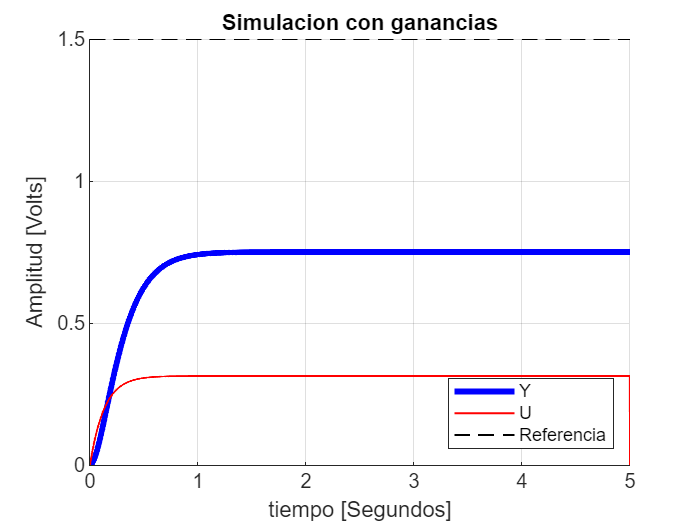


for i = 2:(length(time_vector)-1)

    e0 = reference(i) - y(i);
    e1 = reference(i-1) - y(i-1);
    u1 = u(i-1);

    u(i) = (voltage_e_gains(2)*e1 + voltage_e_gains(1)*e0 + voltage_u_gain*u1);

    % if (u(i) > 5)
    %     u(i) = 5;
    % elseif (u(i) < 0)
    %     u(i) = 0;
    % end

    states = G_A*states + G_B*u(i);
    y(i+1) = G_C*states;

end

% y
% u

figure; hold on; grid on;
plot(time_vector, y, 'b', 'LineWidth', 3);
plot(time_vector, u, 'r', 'LineWidth', 1);
plot(time_vector, reference, '--k', 'LineWidth', 1);

title('Simulacion con ganancias');
ylabel('Amplitud [Volts]');
xlabel('tiempo [Segundos]');
legend('Y', 'U', 'Referencia', 'Location', 'southeast');

Ahora hago lo mismo pero considerando que tengo enteros y ningun flotante para las operaciones

time_vector = 0:Ts:5;

states = zeros(length(G_A), 1);
ref = 1500*2;
r = (ref/2)*ones(1, length(time_vector));
reference = ref*ones(1, length(time_vector));
% perturbance=zeros(1, length(time_vector));perturbance(round(length(perturbance)*0.5):end)=0.2*ref;
% reference=reference-perturbance;
y = zeros(1, length(time_vector));
u = zeros(1, length(time_vector));

% e_gains
% u_gains

fprintf("(%f)e[n] + (%f)e[n-1] + (%f)u[n-1]\n", voltage_e_gains(1), voltage_e_gains(2), voltage_u_gain)

(0.278637)e[n] + (-0.277055)e[n-1] + (0.996216)u[n-1]



GAIN_E_1

GAIN_E_1 = int32
-277

GAIN_E_0

GAIN_E_0 = int32
279

GAIN_U_0

GAIN_U_0 = int32
996

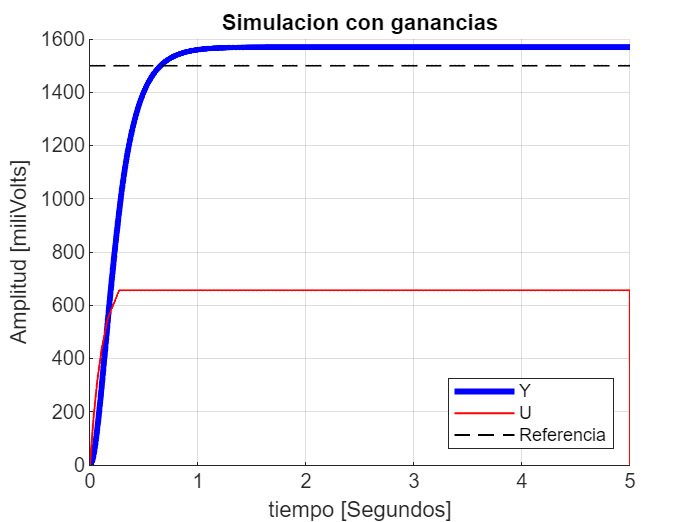


for i = 2:(length(time_vector)-1)

    e0 = reference(i) - y(i);
    e1 = reference(i-1) - y(i-1);
    u1 = u(i-1);

    u(i) = (GAIN_E_1*e1 + GAIN_E_0*e0 + GAIN_U_0*u1) / SCALE;

    % if (u(i) > 5)
    %     u(i) = 5;
    % elseif (u(i) < 0)
    %     u(i) = 0;
    % end

    ui=0;
    if (u(i) > 0)
        ui=u(i);
    end

    states = G_A*states + G_B*ui;
    y(i+1) = G_C*states;

end

% y
% u

figure; hold on; grid on;
plot(time_vector, y, 'b', 'LineWidth', 3);
plot(time_vector, u, 'r', 'LineWidth', 1);
plot(time_vector, r, '--k', 'LineWidth', 1);

title('Simulacion con ganancias');
ylabel('Amplitud [miliVolts]');
xlabel('tiempo [Segundos]');
legend('Y', 'U', 'Referencia', 'Location', 'southeast');